## Load CSV file and Select sets of MNIST data

% Load the CSV file containing the Datasets
m = readmatrix("mnist_train.csv");
% choose the set to process and display
set_num = 10;
% this handles the appropriate variable in function
set = 9*(set_num-1);

## Process and Display the Original MNIST Datasets

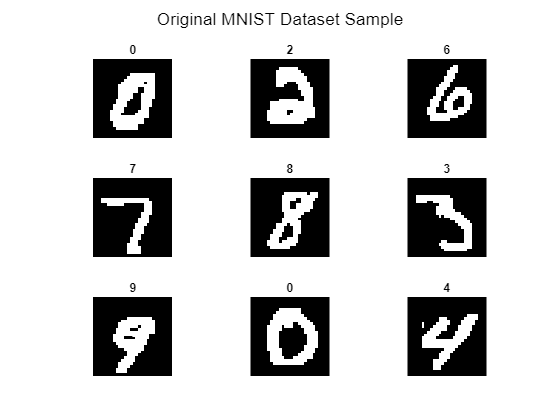

% This section creates the 28x28 MNIST Dataset array
% The first 9 MNIST Dataset is loaded here
for n = 1:9
    position = n;
    % The purpose of this is to reshape the array
    % the MNIST dataset is originally stored as [784,1]
    % here, the array is transformed [784,1] -> [28,28]
    Data = m(position+set,2:29);
    for i = 1:27
        tmp = m(position+set,2+28*i:29+28*i);
        Data = [Data; tmp];
    end 
    % Display of the MNIST Datasets
    subplot(3,3,n);
    imshow(Data,'InitialMagnification',1000); 
    label = m(position+set,1);
    title("" + label)
    sgtitle("Original MNIST Dataset Sample")
end


figure

## Binarize the Pixel Value for the MNIST Datasets

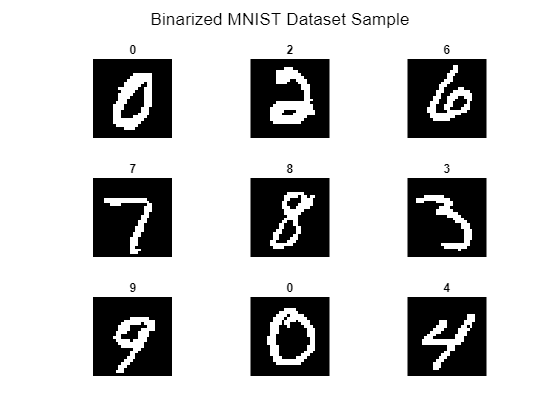

% This section creates the 28x28 MNIST Dataset array
% The first 9 MNIST Dataset is loaded here
for n = 1:9
    position = n;
    % The purpose of this is to reshape the array
    % the MNIST dataset is originally stored as [784,1]
    % here, the array is transformed [784,1] -> [28,28]
    Data_binary = m(position+set,2:29);
    for i = 1:27
        tmp = m(position+set,2+28*i:29+28*i);
        Data_binary = [Data_binary; tmp];
    end 
    % If Pixel value less than 255/2, 
    % the value returns 0 to matrix, else 1
    Data_binary = Data_binary > 100;
    % Display of the MNIST Datasets
    subplot(3,3,n);
    imshow(Data_binary,'InitialMagnification',1000); 
    label = m(position+set,1);
    title("" + label)
    sgtitle("Binarized MNIST Dataset Sample")
end


figure